# Midterm Question #

**Author: Keith Chester**

**E-mail: kchester@wpi.edu**

## Methods

We are looking to use forward kinematics to create a model for the following robotic arm:

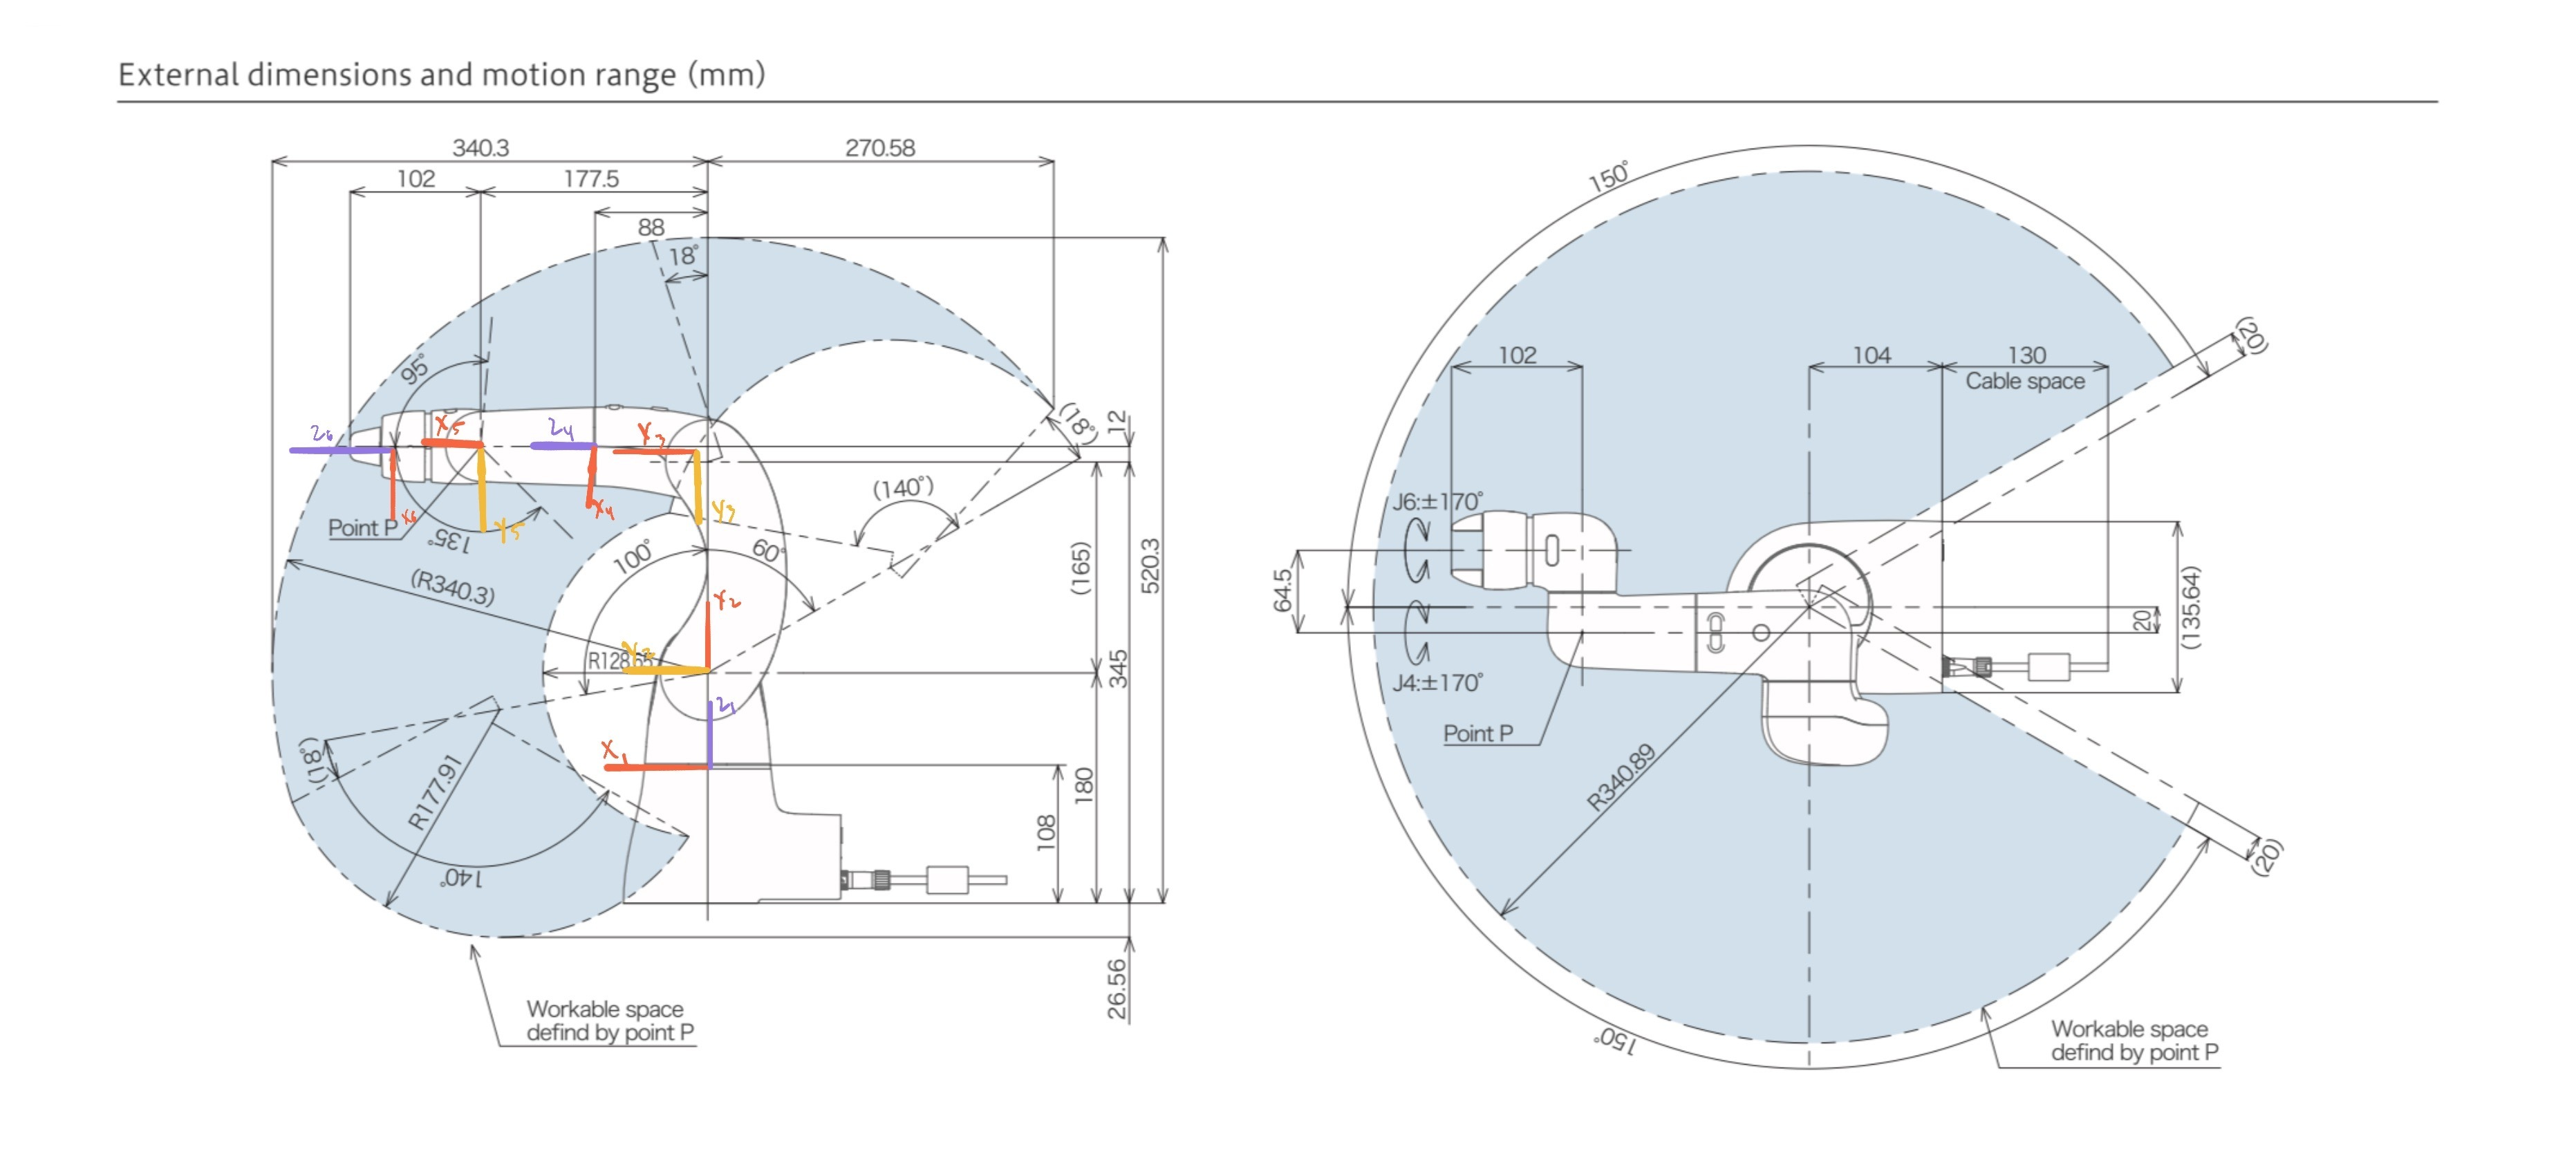

We will be adding coordinate axes to meet the Denavit–Hartenberg (DH) Convention, which will make generating transformation matricies for between links of the robot arm simple and standardized. Note that in the side view, we have already defined these axes over the provided technical image.

We will define each joint $J$as $J_1 \;\mathrm{to}\;J_6$, each with a rotation $\theta_1 \;\mathrm{to}\;\theta_6$ respectively for the arm.

We will use the rotatons of the axes per DH convention and the specified measurements between them to generate a DH table.

syms theta1 theta2 theta3 theta4 theta5 theta6

dh_table = {
    [theta1   165   0        -pi/2],
    [theta2   0     165      pi/2 ],
    [theta3   0    88        pi/2 ],
    [theta4   89.5  0        -pi/2],
    [theta5   64.5  102      pi/2]
}

dh_table = 5×1 cell array
    {1×4 sym}
    {1×4 sym}
    {1×4 sym}
    {1×4 sym}
    {1×4 sym}


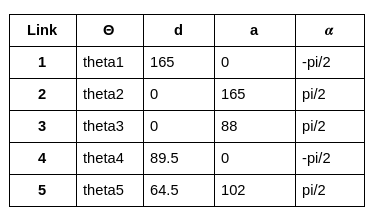

A1 = transform_from_dh_row(dh_table, 1, true)

$$A1 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right) & 0\\ 0 & -1 & 0 & 165\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A2 = transform_from_dh_row(dh_table, 2, true)

$$A2 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & 0 & \sin\left(\theta_{2}\right) & 165\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & 0 & -\cos\left(\theta_{2}\right) & 165\,\sin\left(\theta_{2}\right)\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A3 = transform_from_dh_row(dh_table, 3, true)

$$A3 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & 0 & \sin\left(\theta_{3}\right) & 88\,\cos\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & 0 & -\cos\left(\theta_{3}\right) & 88\,\sin\left(\theta_{3}\right)\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A4 = transform_from_dh_row(dh_table, 4, true)

$$A4 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & 0 & -\sin\left(\theta_{4}\right) & 0\\ \sin\left(\theta_{4}\right) & 0 & \cos\left(\theta_{4}\right) & 0\\ 0 & -1 & 0 & \frac{179}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A5 = transform_from_dh_row(dh_table, 5, true)

$$A5 = \left(\begin{array}{cccc} \cos\left(\theta_{5}\right) & 0 & \sin\left(\theta_{5}\right) & 102\,\cos\left(\theta_{5}\right)\\ \sin\left(\theta_{5}\right) & 0 & -\cos\left(\theta_{5}\right) & 102\,\sin\left(\theta_{5}\right)\\ 0 & 1 & 0 & \frac{129}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

From here, we can gather the transformation matrix from the base 0 frame to each coordinate frame throughout the arm. We can find these by multiplying through the link transformation matricies. As such:


$$\begin{array}{l}
H_1^0 =A_1 \\
H_2^0 =A_1 A_2 \\
H_3^0 =A_1 A_2 A_3 \\
H_4^0 =A_1 A_2 A_3 A_4 \\
H_5^0 =A_1 A_2 A_3 A_4 A_5 
\end{array}$$


or, essentially:

H_0_1 = A1

$$H\_0\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right) & 0\\ 0 & -1 & 0 & 165\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_0_2 = simplify(A1 * A2)

$$H\_0\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & 165\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & 165\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ -\sin\left(\theta_{2}\right) & 0 & \cos\left(\theta_{2}\right) & 165-165\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_0_3 = simplify(A1 * A2 * A3)

$$H\_0\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & 165\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-88\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+88\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\\ \cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right) & 165\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)+88\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+88\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\\ -\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & 165-88\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)-165\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_0_4 = simplify(A1 * A2 * A3 * A4)

H_0_5 = simplify(A1 * A2 * A3 * A4 * A5)

Once we have these transformation matricies, we can begin to draw the arm at each stage of the simulation by calculating the locations of each axis frame within coordinate frame of the 0th base frame for each step.

## Results

Here we'll be generating a simulation of the robotic arm to try and generate the perimeter of the robotic arm's gripper in the closed configuration.

Each joint has a predefined limit. We'll be using the equivalent amount of steps for each limit. The limits are gathered from the technical drawing. If no limit is specified, we assume 360 degrees of available rotation.

steps = 180;
theta1s = linspace(0,150,steps);
theta2s = linspace(-100, 60, steps);
theta3s = linspace(-70, 70, steps);
theta4s = linspace(-85, 85, steps);
theta5s = linspace(-135, 95, steps);

Below we'll generate a 3d plot of the movement of the arm, plotting each endpoint of the atuator.

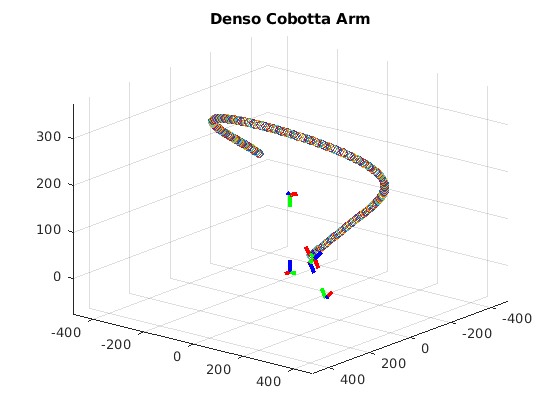

 

animation_length_seconds = 5;

figure
title("Denso Cobotta Arm")
grid on
hold on
xlim([-480 480])
ylim([-480 480])
zlim([-77 374])
view([129 24])
lines = [];
endpoints = {};

for step = 1:steps
    % Clear previous lines
    for index = 1:length(lines)
        delete(lines(index));
    end
    lines = [];
    
    % Set up our dh table for the step
    dh_table = {
        [theta1s(step)   165   0        -90],
        [theta2s(step)   0     165      90 ],
        [theta3s(step)   0    88        90 ],
        [theta4s(step)   89.5  0        -90],
        [theta5s(step)   64.5  102      90]
    };
    
    A1 = transform_from_dh_row(dh_table, 1);
    A2 = transform_from_dh_row(dh_table, 2);
    A3 = transform_from_dh_row(dh_table, 3);
    A4 = transform_from_dh_row(dh_table, 4);
    A5 = transform_from_dh_row(dh_table, 5);
    
    % Calculate our transformations back to 0 frame
    H_0_1 = A1;
    H_0_2 = A1 * A2;
    H_0_3 = A1 * A2 * A3;
    H_0_4 = A1 * A2 * A3 * A4;
    H_0_5 = A1 * A2 * A3 * A4 * A5;
    
    % Draw coordinate axes
    [x_line, y_line, z_line] = draw_coordinate_axis(eye(4), 25, 'red', 'green', 'blue');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    [x_line, y_line, z_line] = draw_coordinate_axis(H_0_1, 25, 'red', 'green', 'blue');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    [x_line, y_line, z_line] = draw_coordinate_axis(H_0_2, 25, 'red', 'green', 'blue');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    [x_line, y_line, z_line] = draw_coordinate_axis(H_0_3, 25, 'red', 'green', 'blue');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    [x_line, y_line, z_line] = draw_coordinate_axis(H_0_4, 25, 'red', 'green', 'blue');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    [x_line, y_line, z_line] = draw_coordinate_axis(H_0_5, 25, 'red', 'green', 'blue');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    

    % Mark the actuator endpoint
    origin = [0; 0; 0; 1;];
    endpoint = H_0_5 * origin;
    plot3(endpoint(1), endpoint(2), endpoint(3), 'o')
    endpoints{end+1} = endpoint;
        
    pause(animation_length_seconds/steps)
    
end

hold off

dkfldskfdsf

steps = 20;
theta1s = linspace(0,150,steps);
theta2s = linspace(-100, 60, steps);
theta3s = linspace(-70, 70, steps);
theta4s = linspace(-85, 85, steps);
theta5s = linspace(-135, 95, steps);

figure
title("Denso Cobotta Arm")
grid on
hold on

for t1 = 1:steps
    for t2 = 1:steps
        for t3 = 1:steps
            for t4 = 1:steps
                for t5 = 1:steps
                    % Set up our dh table for the step
                    dh_table = {
                        [theta1s(t1)   165   0        -90],
                        [theta2s(t2)   0     165      90 ],
                        [theta3s(t3)   0    88        90 ],
                        [theta4s(t4)   89.5  0        -90],
                        [theta5s(t5)   64.5  102      90]
                    };
                    
                    A1 = transform_from_dh_row(dh_table, 1);
                    A2 = transform_from_dh_row(dh_table, 2);
                    A3 = transform_from_dh_row(dh_table, 3);
                    A4 = transform_from_dh_row(dh_table, 4);
                    A5 = transform_from_dh_row(dh_table, 5);
                    H_0_5 = A1 * A2 * A3 * A4 * A5;
                    
                    endpointpoint = H_0_5 * [0; 0; 0; 1;];
                    plot3(endpoint(1), endpoint(2), endpoint(3), 'o')
                end
            end
        end
    end
end

hold off;

### Functions and Classes

#### transform_from_dh_values

This function takes the expected DH values - $\theta$, *d*, *a*, and $\alpha$. It then performs *Equation 1*, listed above.

The use of *vargin* is used to determine if an optional parameter is passed. This optional parameter is used to determine if the caller of the function wishes to make use of symbolic values. If so, we use *cos* and *sin* instead of *cosd *and *sind* respectively. This results in slightly better outputs for symbolic functions.

function H = transform_from_dh_values(theta, d, a, alpha, varargin)
    if nargin == 4
        R_z_theta = [ cosd(theta)      -sind(theta)     0     0;
                      sind(theta)       cosd(theta)     0     0;
                      0                 0               1     0;
                      0                 0               0     1; ];
        R_x_alpha = [ 1     0               0            0;
                      0     cosd(alpha)     -sind(alpha) 0;
                      0     sind(alpha)     cosd(alpha)  0;
                      0     0               0            1; ];
    else
        R_z_theta = [ cos(theta)      -sin(theta)     0     0;
                      sin(theta)       cos(theta)     0     0;
                      0                0              1     0;
                      0                0              0     1; ];
        R_x_alpha = [ 1     0              0            0;
                      0     cos(alpha)     -sin(alpha)  0;
                      0     sin(alpha)     cos(alpha)   0;
                      0     0              0            1; ];
    end
    
    
    T_z_d = [ 1     0      0    0;
              0     1      0    0;
              0     0      1    d;
              0     0      0    1; ];
    
    T_x_a = [ 1     0      0    a;
              0     1      0    0;
              0     0      1    0;
              0     0      0    1; ];
    
    
    
    H = R_z_theta * T_z_d * T_x_a * R_x_alpha;
end

#### transform_from_dh_row

This is a helper function that takes a DH table as defined above (in the form of a cell of matricies of expected DH values in a set standard order of $\theta$, *d*, *a*, and $\alpha$. It then separates out the $\theta$, *d*, *a*, and $\alpha$ of the specified row, and passes it to **transform_from_dh_values**, as described above. The use of *vargin* is passed through, for reasons specified above.

function H = transform_from_dh_row(table, row, vargin)
    theta = table{row}(1);
    d = table{row}(2);
    a = table{row}(3);
    alpha = table{row}(4);
    if nargin == 2
        H = transform_from_dh_values(theta, d, a, alpha);
    else
        H = transform_from_dh_values(theta, d, a, alpha, true);
    end
end

#### draw_coordinate_axis

This function accepts a specified transform, length of the desired axis lines, and the color for each axis. It then draws on the current active figure the origin for that axis based on the transform passed.

function [x_line, y_line, z_line] = draw_coordinate_axis(transform, length, x_color, y_color, z_color)    
    origin = transform * [0; 0; 0; 1;];
    x = transform * [length; 0;         0;      1; ];
    y = transform * [0;      length;    0;      1; ];
    z = transform * [0;      0;         length; 1; ];
    x_line = line('XData', [origin(1) x(1)], 'YData', [origin(2) x(2)], 'ZData', [origin(3) x(3)], 'Color', x_color, 'LineWidth', 3);
    y_line = line('XData', [origin(1) y(1)], 'YData', [origin(2) y(2)], 'ZData', [origin(3) y(3)], 'Color', y_color, 'LineWidth', 3);
    z_line = line('XData', [origin(1) z(1)], 'YData', [origin(2) z(2)], 'ZData', [origin(3) z(3)], 'Color', z_color, 'LineWidth', 3);
end